# Leukemia Drug Interactions Screening Device

GUI implementation allowing for simple controls

Normalized concentrations as multiples of EC50

## Device Implementation

### Cell Seeding

mapNum = 3;
synergyModel = "MuSyC";
switch mapNum
    case 1
        concMap = readtable('xy_25um_c1c2c3.csv');
    case 2
        data = load('ConcentrationMap_3uLpmin3D_D1e-10.mat');
        concMap = array2table(data.concnmap);
    case 3
        data = load('ConcentrationMap_3uLpmin3D_D1e-10 - cropped.mat');
        concMap = array2table(data.cc);
end
% Initialize concentration map
concMap.Properties.VariableNames = {'X', 'Y', 'c1', 'c2', 'c3'};

% Sample a subset of points
n = 3000; % number of cells
[cells, idx] = datasample(concMap, n);
%plot(cells.X, cells.Y,'.b')
%set(gca,'Color','k')

### Cell Properties

drug1_resist = 0; % percentage
drug2_resist = 0; 
drug3_resist = 0;
cell_death = 0;

### Channel Concentration of Drug

Concentration relative to the EC50 (i.e. 1 = EC50, 2 = 2*EC50, etc.)

% Channel A is left of the top, B and C are clockwise away
channel_1_conc = 1; % multiple of EC50
channel_2_conc = 1; % multiple of EC50
channel_3_conc = 1; % multiple of EC50
cells.c1 = concMap.c1(idx).*(channel_1_conc);
cells.c2 = concMap.c2(idx).*(channel_2_conc);
cells.c3 = concMap.c3(idx).*(channel_3_conc);

## Drug Properties

% Real drugs
% Single drug
Emax1 = 0;
hill1 = 3;
Emax2 = 0;
hill2 = 3;
Emax3 = 0;
hill3 = 3;

### Interactions

Synergistic Potency

alpha12 = -4.5;
alpha23 = 0;
alpha13 = 0;

Synergistic Efficacy

beta12 = 0;
beta23 = 0;
beta13 = 0;


drug1 = DrugSingle(Emax1, hill1, 1, 1);
drug2 = DrugSingle(Emax2, hill2, 1, 1);
drug3 = DrugSingle(Emax3, hill3, 1, 1);
drug1.Name = 'Drug 1';
drug2.Name = 'Drug 2';
drug3.Name = 'Drug 3';

% Pairwise combinations
drug12 = DrugCombo(drug1, drug2);
drug12.Alpha = [10^alpha12, 10^alpha12];
drug12.Beta = beta12;

drug23 = DrugCombo(drug2, drug3);
drug23.Alpha = [10^alpha23, 10^alpha23];
drug23.Beta = beta23;

drug13 = DrugCombo(drug1, drug3);
drug13.Alpha = [10^alpha13, 10^alpha13];
drug13.Beta = beta23;

% Triple combination
drugCombination = DrugTri(drug12, drug13, drug23);
drugCombination.Gamma = [1, 1, 1];
drugCombination.Drug1 = drug1;
drugCombination.Drug2 = drug2;
drugCombination.Drug3 = drug3;

## Drug Effect

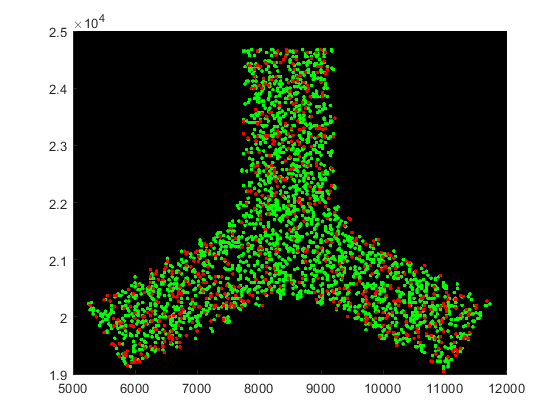

% Bliss model

% Apply MuSyC model
if synergyModel=="MuSyC"
Ed = MuSyC(drugCombination, cells.c1*(100-drug1_resist)/100, ...
    cells.c2*(100-drug2_resist)/100, cells.c3*(100-drug3_resist)/100);
end
% Kill cells according to Ed
live = rand(length(Ed),1)<Ed; % cells that are alive are 1, dead are 0

% Apply random cell death
rand_live = rand(length(Ed),1)>cell_death./100; % 1 means alive, 0 means dead
live = logical(live.*rand_live);

dead = live~=1; % reverse the 0 and 1 for live values
none = zeros(length(cells.c1),1); % blank matrix of image size
cells.live = live;
cells.dead = dead;

figure
hold on
plot(cells.X(live==1), cells.Y(live==1),'g.')
plot(cells.X(live==0), cells.Y(live==0),'r.')
set(gca,'Color','k')
hold off

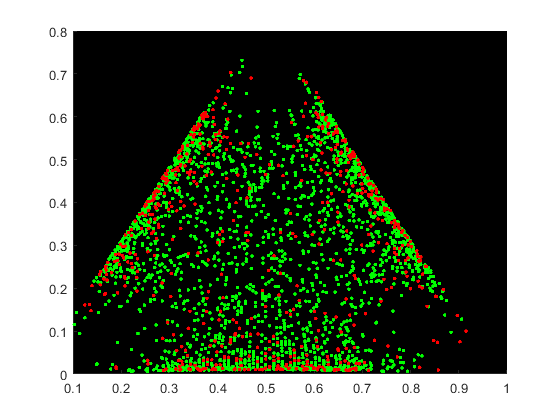



% Ternary plot
a = concMap.c1(idx);
b = concMap.c2(idx);
c = concMap.c3(idx);
ternX = 0.5.*(2.*b+c)./(a+b+c);
ternY = (sqrt(3)./2).*c./(a+b+c);
figure
hold on
plot(ternX(live==1), ternY(live==1),'g.');
plot(ternX(live==0), ternY(live==0),'r.');
set(gca,'Color','k')
hold off

Analysis (10% cutoff)

%{
% Loewe plots?
% Set threshold
a_threshold = channel_1_conc.*0.1; % 10%
idx = find(cells.c1 < a_threshold);
cells_filtered = cells(idx,:);
figure
plot(cells_filtered.c2, cells_filtered.c3, '.b')
plot(log10(cells_filtered.c2./cells_filtered.c3), cells_filtered.live,'.b')
xlabel('ratio of drug2 to drug 3')
ylabel('live/dead')
% Plots for drug 12 vs 3
plot(cells.c1(cells.live==1)+cells.c2(cells.live==1), cells.c3(cells.live==1),'.g')
hold on
plot(cells.c1(cells.live==0)+cells.c2(cells.live==0), cells.c3(cells.live==0),'.r')
hold off
xlabel('drug 1+2')
ylabel('drug 3')

%}
a_threshold = channel_1_conc.*0.1; % 10%
idx_a = find(cells.c1 < a_threshold);
cells_filtered23 = cells(idx_a,:);

b_threshold = channel_2_conc.*0.1; % 10%
idx_b = find(cells.c2 < b_threshold);
cells_filtered13 = cells(idx_b,:);

c_threshold = channel_3_conc.*0.1; % 10%
idx_c = find(cells.c3 < c_threshold);
cells_filtered12 = cells(idx_c,:);

viability12 = sum(cells_filtered12.live)/height(cells_filtered12)

viability12 = 0.8003

viability13 = sum(cells_filtered13.live)/height(cells_filtered13)

viability13 = 0.7405

viability23 = sum(cells_filtered23.live)/height(cells_filtered23)

viability23 = 0.7739

viabilitycenter = cells.live;
viabilitycenter([idx_a; idx_b; idx_c]) = [];
viabilitycenter = sum(viabilitycenter)/height(viabilitycenter)

viabilitycenter = 0.8696


% Do studies looking only at viability12 compared to control drugs
synThreshold = 0.2; % 40%
synDiff = (min([viability23, viability13])-viability12)/(min([viability23, viability13]))

synDiff = -0.0807

if synDiff > synThreshold
    synBool = true;
else
    synBool = false;
end
synBool

synBool = logical
   0
